# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 18-Dec-2025 10:25:07

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 5, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Date_Time", "LVActivePower_kW_", "WindSpeed_m_s_", "Theoretical_Power_Curve_KWh_", "WindDirection___"];
opts.VariableTypes = ["string", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Date_Time", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Date_Time", "EmptyFieldRule", "auto");

% Import the data
T1 = readtable("C:\Users\keski\OneDrive\Masaüstü\Rüzgar Projesi\T1.csv", opts)

T1 = 50530×5 table
        Date_Time         LVActivePower_kW_    WindSpeed_m_s_    Theoretical_Power_Curve_KWh_    WindDirection___
    __________________    _________________    ______________    ____________________________    ________________

    "01 01 2018 00:00"         380.05              5.3113                   416.33                    259.99     
    "01 01 2018 00:10"         453.77              5.6722                   519.92                    268.64     
    "01 01 2018 00:20"         306.38               5.216                    390.9                    272.56     
    "01 01 2018 00:30"         419.65              5.6597                   516.13                    271.26     
    "01 01 2018 00:40"         380.65              5.5779                    491.7                    265.67     
    "01 01 2

## Clear temporary variables

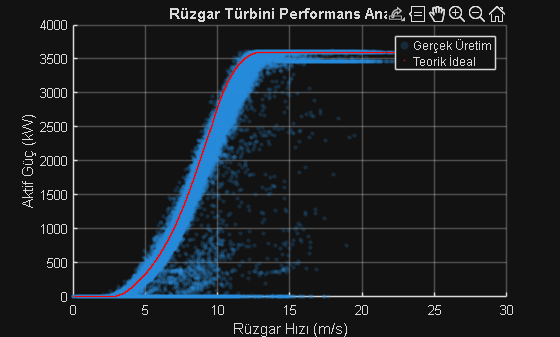

clear opts

%% --- MÜHENDİSLİK ANALİZLERİ BAŞLANGICI ---

% 1. İlk Grafik: Güç Eğrisi (Gerçek vs Teorik)
figure;
scatter(T1.WindSpeed_m_s_, T1.LVActivePower_kW_, 10, 'filled', 'MarkerFaceAlpha', 0.2);
hold on;
plot(T1.WindSpeed_m_s_, T1.Theoretical_Power_Curve_KWh_, 'r.', 'MarkerSize', 2);
xlabel('Rüzgar Hızı (m/s)'); ylabel('Aktif Güç (kW)');
title('Rüzgar Türbini Performans Analizi');
legend('Gerçek Üretim', 'Teorik İdeal'); grid on;


% 2. Veri Onarımı
% Hatalı (0 veya altı) değerleri temizleyip Spline ile dolduruyoruz
T1.OnarilmisGuc = T1.LVActivePower_kW_;
T1.OnarilmisGuc(T1.OnarilmisGuc <= 0) = NaN;
T1.OnarilmisGuc = fillmissing(T1.OnarilmisGuc, 'spline');
disp('Veri onarımı (Kübik Spline) tamamlandı.');

Veri onarımı (Kübik Spline) tamamlandı.




% Hatalı (0 veya negatif) değerleri NaN (boş) yapıp spline ile doldur
T1.OnarilmisGuc = T1.LVActivePower_kW_;
T1.OnarilmisGuc(T1.OnarilmisGuc <= 10) = NaN; % 10 kW altı genelde hatadır
T1.OnarilmisGuc = fillmissing(T1.OnarilmisGuc, 'spline');

disp('Veri onarımı (Kübik Spline) başarıyla tamamlandı.');

Veri onarımı (Kübik Spline) başarıyla tamamlandı.


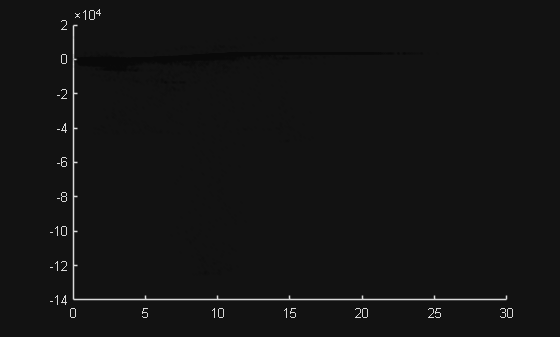


% Rüzgar hızına göre güç tahmini yapan 3. derece bir model
p = polyfit(T1.WindSpeed_m_s_, T1.OnarilmisGuc, 3);
tahmin_guc = polyval(p, T1.WindSpeed_m_s_);

% --- GÜNCEL TAHMİN GRAFİĞİ (HATASIZ) ---
figure;
% Scatter ile şeffaf noktalar çiziyoruz (MarkerAlpha burada çalışır)
scatter(T1.WindSpeed_m_s_, T1.OnarilmisGuc, 5, 'black', 'filled', 'MarkerFaceAlpha', 0.05); 
hold on;


% Tahmin çizgisi için düzgün bir hat oluşturalım
[sirali_hiz, idx] = sort(T1.WindSpeed_m_s_);
sirali_tahmin = tahmin_guc(idx);

% --- GÜNCEL TAHMİN GRAFİĞİ (DAHA NET GÖRÜNÜM) ---
figure;
% Verileri siyah noktalar olarak çizelim
scatter(T1.WindSpeed_m_s_, T1.OnarilmisGuc, 3, 'black', 'filled', 'MarkerFaceAlpha', 0.1); 
hold on;

% Kırmızı tahmin çizgisini rüzgar hızına göre sıralayıp çizdirelim
[sirali_hiz, idx] = sort(T1.WindSpeed_m_s_);
sirali_tahmin = tahmin_guc(idx);
plot(sirali_hiz, sirali_tahmin, 'r-', 'LineWidth', 3);

% Grafik sınırlarını veriye göre sabitleyelim (0-25 m/s rüzgar, 0-4000 kW güç)
axis([0 25 0 4000]); 

title('Rüzgar Hızı - Güç Tahmin Modeli (Onarılmış Veri)');
xlabel('Rüzgar Hızı (m/s)');
ylabel('Üretilen Güç (kW)');
legend('Gerçek Veri (Onarılmış)', 'Regresyon Tahmin Hattı');

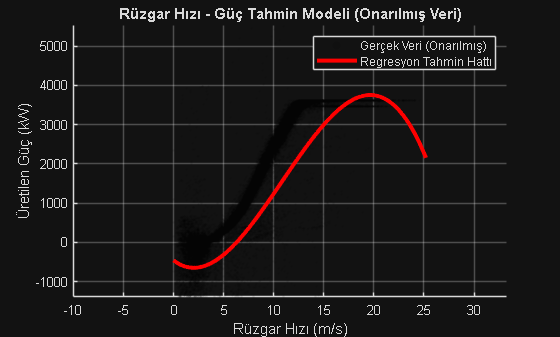

grid on;